clc;
clear all;
% Define Stewart Platform Geometry
baseRadius = 75; % Radius of the base
platformRadius = 75; % Radius of the moving platform
legLengthMin = 119; % Minimum length of the legs
legLengthMax = 140.1; % Maximum length of the legs

% Define attachment points on the base (assumed to be at 60 degrees apart)
% [0.23247, 0.81184, 2.3297, 2.9091]
theta = linspace(0, 2*pi, 7)

theta =          0    1.0472    2.0944    3.1416    4.1888    5.2360    6.2832


theta(end) = []

theta =          0    1.0472    2.0944    3.1416    4.1888    5.2360


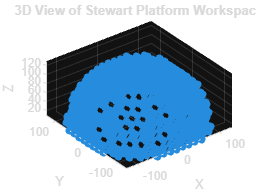

% basePoints = 
basePoints = baseRadius * [cos(theta); sin(theta); zeros(1, 6)];

% Define attachment points on the moving platform
platformPoints = platformRadius * [cos(theta); sin(theta); zeros(1, 6)];

% Workspace grid resolution
xRange = -200:15:200;
yRange = -200:15:200;
zRange = -200:15:200;
[X, Y, Z] = meshgrid(xRange, yRange, zRange);

% Initialize workspace matrix
workspace = zeros(size(X));

% Loop through all grid points
for ix = 1:length(xRange)
    for iy = 1:length(yRange)
        for iz = 1:length(zRange)
            % Current position of the moving platform
            p = [xRange(ix); yRange(iy); zRange(iz)];
            
            % Ignore any value that has a negative z-coordinate
            if p(3) < 0
                continue;
            end
            
            % Check if this position is reachable
            reachable = true;
            for i = 1:6
                % Leg length
                legLength = norm(p + platformPoints(:,i) - basePoints(:,i));
                
                % Check if leg length is within limits
                if legLength < legLengthMin || legLength > legLengthMax
                    reachable = false;
                    break;
                end
            end
            
            % Mark the point in the workspace
            if reachable
                workspace(ix, iy, iz) = 1;
            end
        end
    end
end

% Visualize the Workspace from different views
figure;

% 3D view
% % subplot(2, 2, 1);
scatter3(X(workspace == 1), Y(workspace == 1), Z(workspace == 1), 'filled');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D View of Stewart Platform Workspace');
grid on;
axis equal;

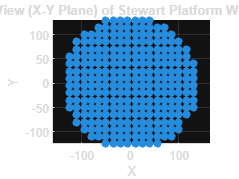


figure
% Top view (X-Y plane)
% subplot(2, 2, 2);
scatter(X(workspace == 1), Y(workspace == 1), 'filled');
xlabel('X');
ylabel('Y');
title('Top View (X-Y Plane) of Stewart Platform Workspace');
grid on;
axis equal;

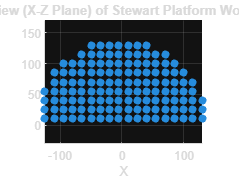

% view(2); % Top view

figure
% Side view (X-Z plane)
% subplot(2, 2, 3);
scatter(X(workspace == 1), Z(workspace == 1), 'filled');
xlabel('X');
zlabel('Z');
title('Side View (X-Z Plane) of Stewart Platform Workspace');
grid on;
axis equal;

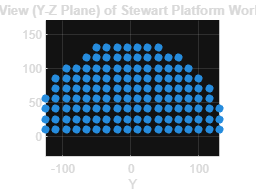

% view([1, 0, 0]); % Side view (X-Z plane)

figure
% Side view (Y-Z plane)
% subplot(2, 2, 4);
scatter(Y(workspace == 1), Z(workspace == 1), 'filled');
xlabel('Y');
zlabel('Z');
title('Side View (Y-Z Plane) of Stewart Platform Workspace');
grid on;
axis equal;

% view([0, 1, 0]); % Side view (Y-Z plane)